close all
clc
load PETdata.mat
addpath("Functions\")

test_img = 10;

## Part A  - Forward Projection

# A1

*Q: Write a function that returns the matrix A given the projectionangles, the size of the sinogram and the dimensions of the image*

thetas = 0:(size(G, 2)-1); % 0:179 
L = size(G, 1); 
R = L; C = L;

A = compute_forward_matrix(thetas, L, R, C);

# A2

**Q: *****To include in the report****: A reconstructed slice of the noise free data.*

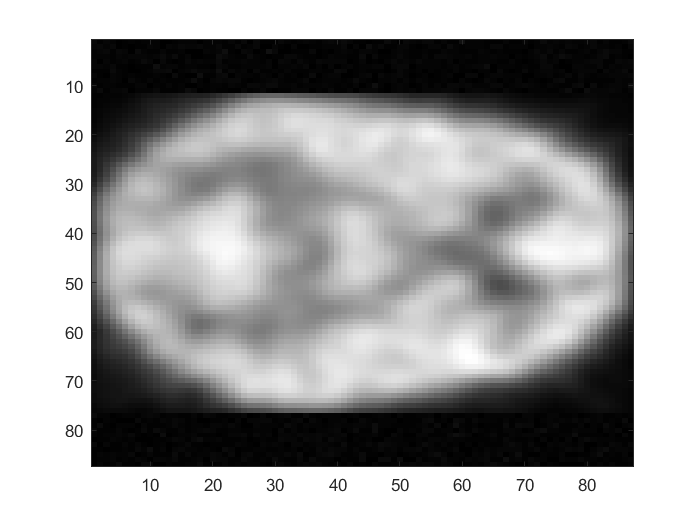

rec = NAIVE(A, G(:,:,test_img), [L, L, 1]);
imagesc(rec); colormap gray

## Part B - Iterative Reconstruction

# B1

**Q: To in-clude in the report: ***The derivations of the log-likelihood function.*

Assume that $g_i$ is a Poisson distributed variable. Then the probability mass function is given as


$$P\left(g_i \right)=e^{-\bar{g_i } } \frac{\bar{g_i } }{g_i !}$$


The likelihood function, considering an iid sample of $g_i$ from a Poisson distribution,


$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)=P\left(g_{\;i} =g_{i1} \right)P\left(g_i =g_{i2} \right)\ldotp \ldotp \ldotp P\left(g_i =g_{\textrm{in}} \right)$$



$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)=\;$$

$$e^{-\bar{g_{\textrm{i1}} } } \frac{\bar{g_{\textrm{i1}} } }{g_{\textrm{i1}} !}e^{-\bar{g_{\textrm{i2}} } } \frac{\bar{g_{\textrm{i2}} } }{g_{\textrm{i2}} !}\ldotp \ldotp \ldotp e^{-\bar{g_{\textrm{in}} } } \frac{\bar{g_{\textrm{in}} } }{g_{\textrm{in}} !}$$



$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\;=e^{-n\;\bar{g_i } } \frac{{\bar{g_i } }^{\sum_n g_i } }{\prod_n g_i !}$$


Then the log-likelihood is simply the logarithm of the above expression:


$$\ln \left(L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\right)=-n\bar{g_i } +\left(\sum_n g_i \right)\ln \left(g_i \right)+\ln \left(\prod_n g_i !\right)$$


The derivative of this expression yields the Maximum Likelihood Estimator (MLE). We differentiate it with respect to $\bar{g_i }$.


$$\frac{d}{d\bar{g_i } }$$

$$\ln \left(L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\right)=-n+\frac{\left(\sum_n g_i \right)}{\hat{g_i } }$$
 

Setting to 0 and solving for $\hat{g_i }$ yields the MLE:


$$\hat{g_i } =\frac{\sum_n g_i }{n}$$


# B2

***Q: To include in the report:**** A reconstructed slice for different iteration numbers and a plot of the sum-of-squared residuals vs iteration number.*

    "num iters"    "10"



    "num iters"    "20"



    "num iters"    "50"



    "num iters"    "75"



    "num iters"    "100"



    "num iters"    "200"



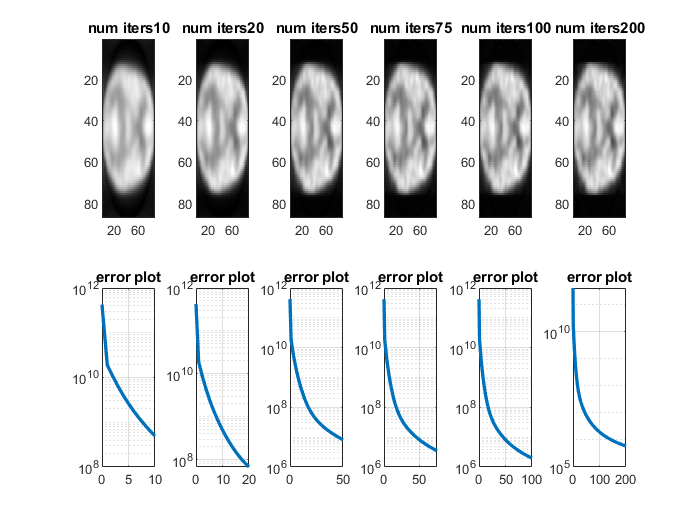

num_iters = [10 20 50 75 100 200];
figure()
plotGrid(A, G(:,:,test_img),@MLEM, num_iters) % see plotGrid at the end of this file

## Part C - Iterative Reconstruction with Noisy Data

# C1

**Q: To include in the report: ***A slice of the reconstructed noisy image (and comments).*

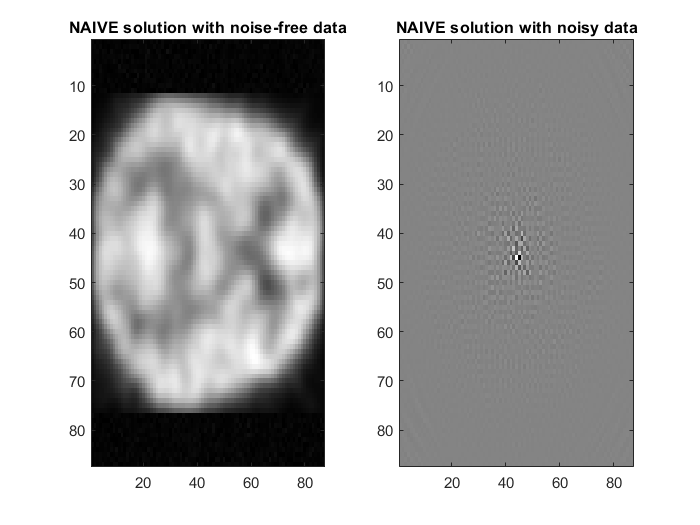

figure()

rec_noisy = NAIVE(A, G_noisy(:,:,10), [L,L,1]);
imagesc(rec_noisy); colormap gray
title("NAIVE solution with noisy data")

Slice of the noisy data. With the noisy data it doesn't seem like the naive version is working at all. 

# C2

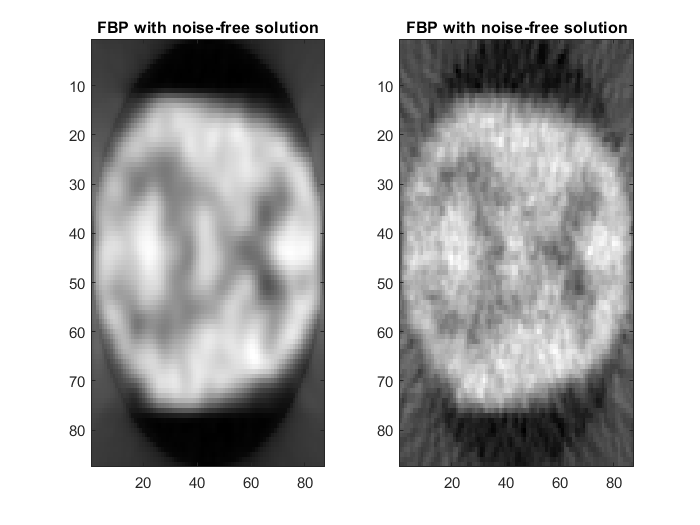

figure()
rec_FBP = FBP(G(:,:,10), thetas, [L, L, 1]);
subplot(1, 2, 1)
imagesc(rec_FBP); colormap gray
title("FBP with noise-free data")

rec_FBP_noisy = FBP(G_noisy(:,:,10), thetas, [L, L, 1]);
subplot(1, 2, 2)
imagesc(rec_FBP_noisy); colormap gray
title("FBP with noisy data")

Noise-free FBP reconstruction to the left and noisy to the right. While blurry, in the noise-free reconstruction contrast can be seen more clearly than in the noisy reconstruction. For instance, slightly gray areas can to some extent be found in the noise-free reconstruction while in the noisy reconstruction it is hard to determine if this are instead noise. 

# C3

**Q: To include in the report: ***A reconstructed slice for different iteration numbers with comments.  A discussion how your observations be explained in terms of ****overfitting****.*

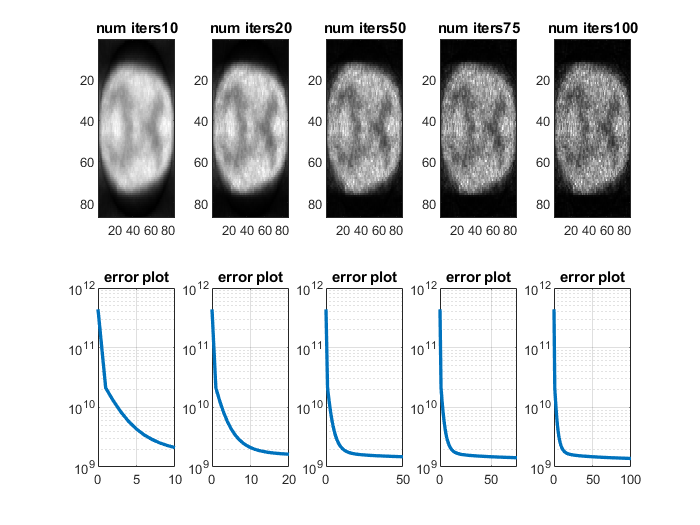

    "num iters"    "10"



    "num iters"    "20"



    "num iters"    "50"



    "num iters"    "75"



    "num iters"    "100"



num_iters = [10 20 50 75 100];
figure()
plotGrid(A, G_noisy(:,:,test_img),@MLEM, num_iters)

# C4

**Q; To includein the report:***A  slice  of  the  noisy  image  obtained  from  the  iterativereconstruction, and comments on the difference to the corresponding sliceobtained from FBP in task C2.  A discussion why the sum-of-squared dif-ference between the sinogram and the forward projection (the error in B2)cannot be used to find an optimal number of iterations given noisy data.*

f_error = zeros(length(num_iters), 1);
i = 1;
for n = num_iters
    disp(["num iters" n])
    [rec_MLEM_noisy, r_error_noisy] = MLEM(A, G_noisy(:,:,10), [L, L, 1], n);
    f_error(i) = sumsqr(rec_MLEM_noisy - rec_MLEM);
    i = i+1;
end

    "num iters"    "10"

    "num iters"    "20"

    "num iters"    "50"

    "num iters"    "75"

    "num iters"    "100"



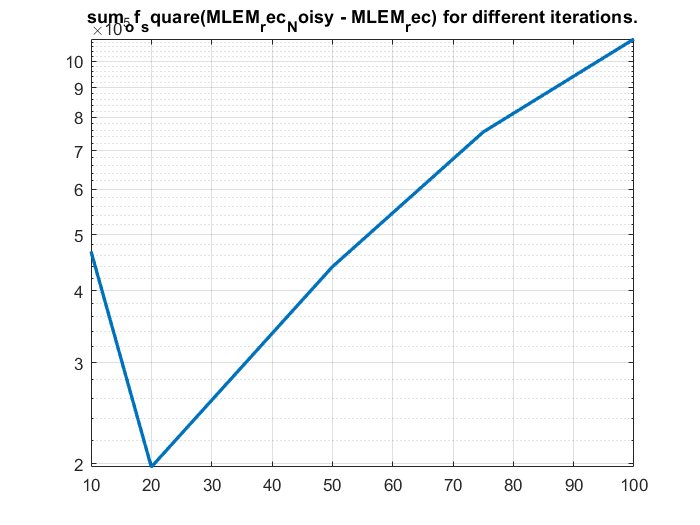

figure()
semilogy(num_iters, f_error, 'LineWidth', 2)
grid on
title("sum_of_square(MLEM_rec_Noisy - MLEM_rec) for different iterations.")

## Helper Function

function plotGrid(A, G,MLEM_func, num_iters)
    
    L = size(G, 1); 
    R = L; C = L;
    num_imgs = size(G, 3);
    
    i = 1;
    for n = num_iters
        disp(["num iters" n])
        [rec_MLEM, r_error] = MLEM_func(A, G, [R, C, num_imgs], n);
        
        % plot only the results of the first image
        subplot(2, length(num_iters), i)
        set(gca, 'YScale', 'linear')
        imagesc(rec_MLEM(:,:,1)); colormap gray
        title(['num iters', num2str(n)])
        
        subplot(2, length(num_iters), length(num_iters) + i)
        set(gca, 'YScale', 'log')
        semilogy(0:n, r_error, 'LineWidth', 2)
        grid on
        title("error plot" )
        
        i = i + 1;
    end

end